%%%Simulation Parameters
m1  = 7;
m2  = 10;
l1  = 0.2; 
l2  = 0.8;
r1  = 0.20; 
r2  = 0.15;
g   = 9.81;
%%%%%new rotation center
cd  = [0,0,-l2/2]';

theta1 = 0;
theta2 = 0;

%%A alpha d theta
dhparams = [0   pi/2  l1 theta1;
            l2  0   0 theta2];

telescope = rigidBodyTree('DataFormat','column','MaxNumBodies',2);

bodies = cell(2,1);
joints = cell(2,1);
for i = 1:2
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
    setFixedTransform(joints{i},dhparams(i,:),"dh");
    bodies{i}.Joint = joints{i};
    if i == 1 % Add first body to base
        addBody(telescope,bodies{i},"base")
    else % Add current body to previous body by name
        addBody(telescope,bodies{i},bodies{i-1}.Name)
    end
end

showdetails(telescope);

--------------------
Robot: (2 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   
--------------------


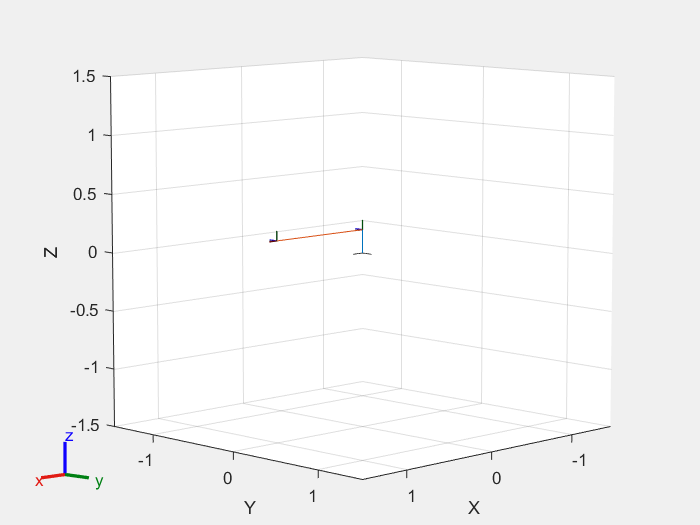

figure(Name="Telescope Model")
show(telescope,[0,0]');

%figure(Name="Interactive GUI")
%gui = interactiveRigidBodyTree(telescope,MarkerScaleFactor=0.5);

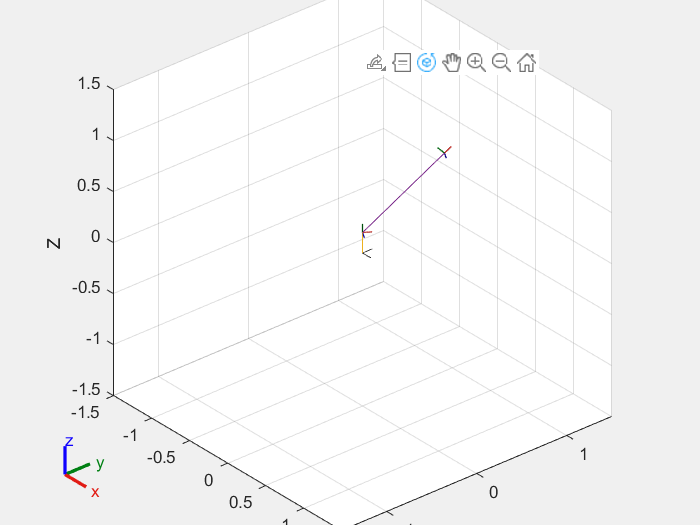

figure
show(telescope,out.q(1,1:2)');
view(2)
count = length(out.tout);
ax = gca;
ax.Projection = 'orthographic';
hold on
%plot3(points(:,1),points(:,2),points(:,3),'k')
%axis([-0.1 0.7 -0.3 0.5])

%%
% Set up a <docid:robotics_ref.mw_9b7bd9b2-cebc-4848-a38a-2eb93d51da03 Rate> object to display the robot 
% trajectory at a fixed rate of 15 frames per secxond. Show the robot in
% each configuration from the inverse kinematic solver. Watch as the arm
% traces the circular trajectory shown.
framesPerSecond = 50;
r = rateControl(framesPerSecond);
for i = 1:count
    show(telescope,out.q(i,1:2)','PreservePlot',false);
    drawnow
    waitfor(r);
end

## Direct Kinematics

transform = getTransform(telescope,[0,0]',"body1","body2")

transform =      1     0     0    -1
     0     1     0     0
     0     0     1     0
     0     0     0     1


## Inverse Dynamics

%% Define the Trajectory
% Define a circle to be traced over the course of 10 seconds. This circle
% is in the _xy_-plane with a radius of 0.15.
t = (0:0.2:10)'; % Time
count = length(t);
center = [0 0 2.1142];
radius = 1.4142;
theta = t*(2*pi/t(end));
points = center + radius*[cos(theta) sin(theta) zeros(size(theta))];

%%figure()
%%plot3(points(:,1),points(:,2),points(:,3));

%% Inverse Kinematics Solution
% Use an |inverseKinematics| object to find a solution of robotic 
% configurations that achieve the given end-effector positions along the 
% trajectory. 

%%
% Pre-allocate configuration solutions as a matrix |qs|.
q0 = homeConfiguration(telescope);
ndof = length(q0);
qs = zeros(count, ndof);
%%
% Create the inverse kinematics solver. Because the _xy_ Cartesian points are the
% only important factors of the end-effector pose for this workflow, 
% specify a non-zero weight for the fourth and fifth elements of the 
% |weight| vector. All other elements are set to zero.
ik = inverseKinematics('RigidBodyTree', telescope);
weights = [0, 0, 0, 1, 1, 0];
endEffector = 'body2';

%%
% Loop through the trajectory of points to trace the circle. Call the |ik|
% object for each point to generate the joint configuration that achieves
% the end-effector position. Store the configurations to use later.

qInitial = q0; % Use home configuration as the initial guess
for i = 1:count
    % Solve for the configuration satisfying the desired end effector
    % position
    point = points(i,:);
    qSol = ik(endEffector,trvec2tform(point),weights,qInitial);
    % Store the configuration
    qs(i,:) = qSol;
    % Start from prior solution
    qInitial = qSol;
end

%% Animate the Solution
% Plot the robot for each frame of the solution using that specific robot 
% configuration. Also, plot the desired trajectory.

%%
% Show the robot in the first configuration of the trajectory. Adjust the 
% plot to show the 2-D plane that circle is drawn on. Plot the desired 
% trajectory.
figure
show(telescope,qs(1,:)');
view(2)
ax = gca;
ax.Projection = 'orthographic';
hold on
plot3(points(:,1),points(:,2),points(:,3),'k')
%axis([-0.1 0.7 -0.3 0.5])

%%
% Set up a <docid:robotics_ref.mw_9b7bd9b2-cebc-4848-a38a-2eb93d51da03 Rate> object to display the robot 
% trajectory at a fixed rate of 15 frames per second. Show the robot in
% each configuration from the inverse kinematic solver. Watch as the arm
% traces the circular trajectory shown.
framesPerSecond = 15;
r = rateControl(framesPerSecond);
for i = 1:count
    show(telescope,qs(i,:)','PreservePlot',false);
    drawnow
    waitfor(r);
end


% %%%%%Inercia del cilindro
% %%%%%Inercia de eslabon 1
% I_1 = diag([1/12*m1*(3*r1^2+l1^2),1/12*m1*(3*r1^2+l1^2),1/2*m1*r1^2]); 
% %%%%%Inercia de eslabon 2 at joint 2
% I_c = diag([1/12*m2*(3*r2^2+l2^2),1/12*m2*(3*r2^2+l2^2),1/2*m2*r2^2]); 
% %%%%%Paralel theorem to get the position at CG
% I_2 = I_c+m2*skew(cd)*skew(cd)';


## Calculate model

% theta1=0;
% theta2=0;
% thetha1_dot = 0;
% 
 M=[I_1(3,3)^2+m2*l2^2*cos(theta2)^2+I_2(3,3), 0
     0, m2*l2^2+I_2(2,2)];
 C=[0; -m2*l2^2*cos(theta2)*sin(theta2)*thetha1_dot^2];
 G=[0; -m2*g*l2/2*cos(theta2)];
% 
% 